Welcome to the Q-Bat tutorial, in which we will simulate the thermal behaviour of the power tool's battery pack during normal operation, rapid charging and cell malfunction event.

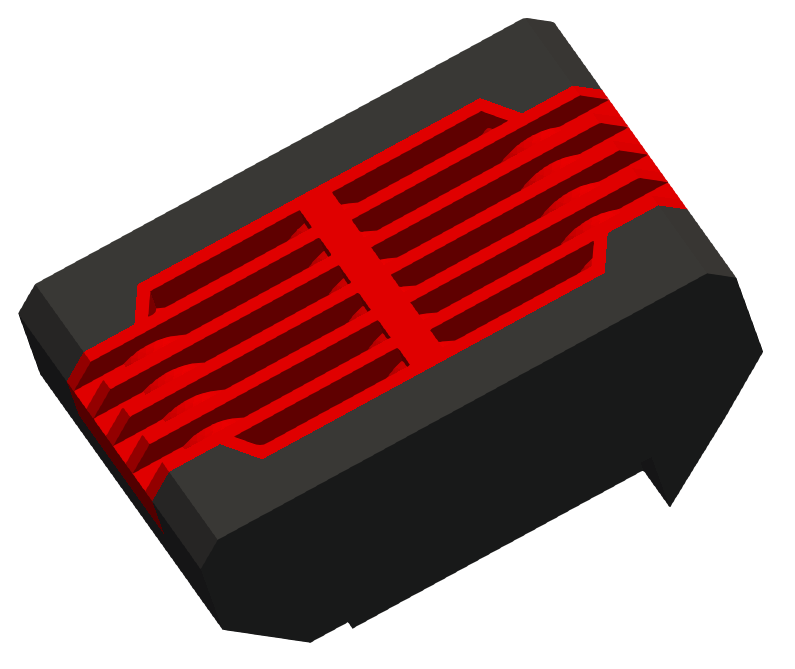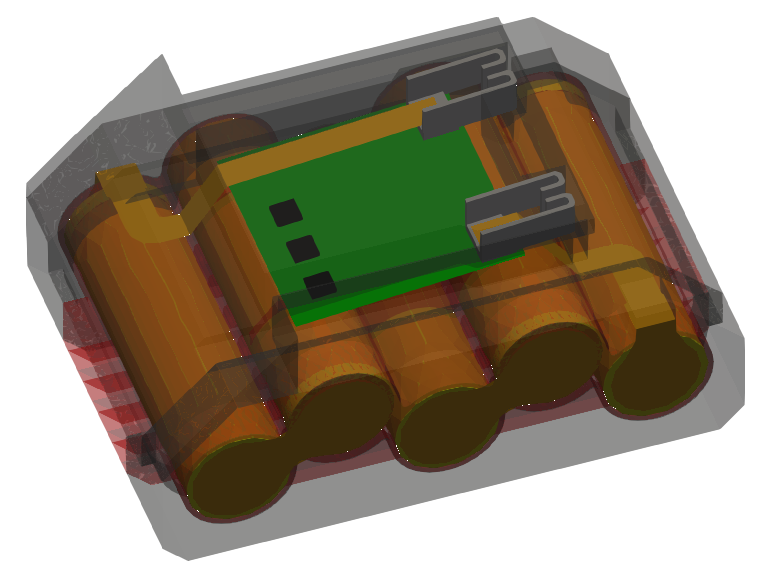

Our model imitates a generic power tool battery pack and consists of 5 cylindrical cells, casing, connectors, bus bars, terminals, circuit board and transistors. We have prepared the model as shown in the picture above. 

## Model preparation

Let's start with clearing your workspace and loading the battery model.

clc
clear
close all

model = loadModel('power_tools_model.mat');

You can display model parts by reference to their component name using the following command:

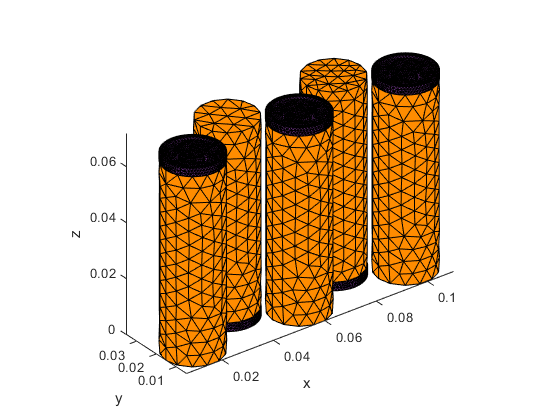

cells = ["cell_core_1", "cell_core2_1", "cell_core_3", "cell_core_4", ...
"cell_core_5", "cell_terminal_1", "cell_terminal_2", "cell_terminal_3", ...
"cell_terminal_4", "cell_terminal_5"];

casings = ["casing_side_1", "casing_side_2", "casing_middle_1_1", ...
"casing_top_1_1"];

misc_parts = ["connector1_1", "connector1_2", "connector1_3", ...
"connector1_4", "connector2_1", "connector2_2", "terminal_1", ...
"terminal_2", "bus_bar1_1_1", "bus_bar2_1_1", "board_1_1", ...
"transistor_1", "transistor_2", "transistor_3"];
model.displayComponents(cells);

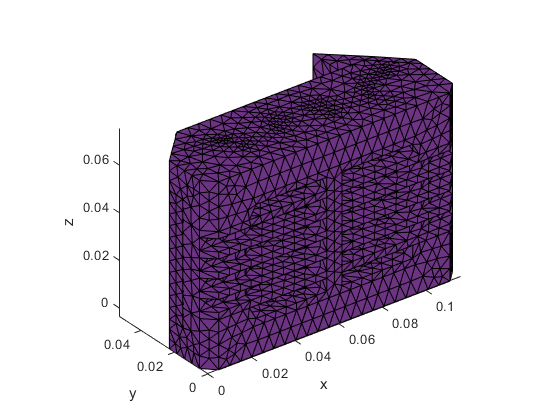

model.displayComponents(casings);

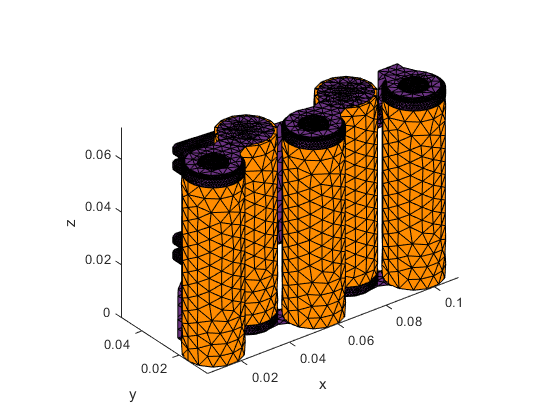

model.displayComponents([cells, misc_parts]);

The model has been prepared with our GUI pre-processor. You can access it by the following command. All of the model preparation steps such as detecting contacts, creating electrical circuits and applying boundary conditions can be easily done using our GUI wizard, however, for your convenience, we have prepared it in the form of a ready-to-go script.

% w = wizard.WizardGUI();

The next model preparation step is grouping components into assemblies and establishing contacts between them.

tic;

% cells together
model.createAssembly("cells_together", ["cell_core_1", "cell_core2_1", ...
   "cell_core_3", "cell_core_4", "cell_core_5", "cell_terminal_1", ...
   "cell_terminal_2", "cell_terminal_3", "cell_terminal_4", "cell_terminal_5"], ...
   "create_all_contacts", true, "contact_conductivity", 100, ...
   "contact_thickness", 1e-3);

Preprocessing contacts...
Found planar contact between: "cell_core_1" - "cell_terminal_2"
Found planar contact between: "cell_core_3" - "cell_terminal_3"
Found planar contact between: "cell_core_4" - "cell_terminal_4"
Found planar contact between: "cell_core_5" - "cell_terminal_1"
Found planar contact between: "cell_terminal_5" - "cell_core2_1"
Found planar contact between: "cell_terminal_5" - "cell_core2_1"
Created 6 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


% cells with middle casing 
model.createAssembly("cells_to_casing_middle", ["cells_together", ...
    "casing_middle_1_1"], ...
    "create_all_contacts", true, "contact_conductivity", 0.01, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Found cylindrical contact between: "cell_core_1" - "casing_middle_1_1"
Found cylindrical contact between: "cell_core_3" - "casing_middle_1_1"
Found cylindrical contact between: "cell_core_4" - "casing_middle_1_1"
Found cylindrical contact between: "cell_core_5" - "casing_middle_1_1"
Found planar contact between: "casing_middle_1_1" - "cell_terminal_1"
Found cylindrical contact between: "cell_terminal_1" - "casing_middle_1_1"
Found planar contact between: "casing_middle_1_1" - "cell_terminal_2"
Found cylindrical contact between: "cell_terminal_2" - "casing_middle_1_1"
Found planar contact between: "casing_middle_1_1" - "cell_terminal_3"
Found cylindrical contact between: "cell_terminal_3" - "casing_middle_1_1"
Found planar contact between: "casing_middle_1_1" - "cell_terminal_4"
Found cylindrical contact between: "cell_terminal_4" - "casing_middle_1_1"
Found planar contact between: "casing_middle_1_1" - "cell_terminal_5"
Found cylindrical contact between: "cell

% cell terminals to connectors
model.createAssembly("cells_to_connectors", ["cells_together", ...
    ["connector1_1", "connector1_2", "connector1_3", "connector1_4", ...
    "connector2_1", "connector2_2"]], ...
    "create_all_contacts", true, "contact_conductivity", 100, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Found planar contact between: "connector2_1" - "cell_core_1"
Found planar contact between: "connector1_1" - "cell_core_3"
Found planar contact between: "connector1_2" - "cell_core_4"
Found planar contact between: "connector1_4" - "cell_core_5"
Found planar contact between: "connector1_3" - "cell_terminal_1"
Found planar contact between: "connector1_2" - "cell_terminal_2"
Found planar contact between: "connector2_2" - "cell_terminal_3"
Found planar contact between: "connector1_4" - "cell_terminal_4"
Found planar contact between: "connector1_1" - "cell_terminal_5"
Found planar contact between: "connector1_3" - "cell_core2_1"
Created 10 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


% connectors to bus bars
model.createAssembly("connectors_to_bus_bars", ["cells_to_connectors", ...
    ["bus_bar1_1_1", "bus_bar2_1_1"]], ...
    "create_all_contacts", true, "contact_conductivity", 100, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Found planar contact between: "bus_bar2_1_1" - "connector2_1"
Found planar contact between: "bus_bar1_1_1" - "connector2_2"
Created 2 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


% terminals together
model.createAssembly("terminals_together", ["terminal_1", "terminal_2"], ...
    "create_all_contacts", true, "contact_conductivity", 100, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Created 0 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


% bus bars to terminals
model.createAssembly("bus_bars_to_terminals", ["connectors_to_bus_bars", ...
    "terminals_together"], ...
    "create_all_contacts", true, "contact_conductivity", 100, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Found planar contact between: "terminal_1" - "bus_bar1_1_1"
Found planar contact between: "terminal_2" - "bus_bar2_1_1"
Created 2 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


% board to terminals
model.createAssembly("board_to_terminals", ["board_1_1", ...
    "terminals_together"], ...
    "create_all_contacts", true, "contact_conductivity", 100, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Found planar contact between: "board_1_1" - "terminal_1"
Found planar contact between: "board_1_1" - "terminal_2"
Created 2 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


% transistors to board
model.createAssembly("transistors_to_board", ["board_1_1", ...
    "transistor_1", "transistor_2", "transistor_3"], ...
    "create_all_contacts", true, "contact_conductivity", 100, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Found planar contact between: "board_1_1" - "transistor_1"
Found planar contact between: "board_1_1" - "transistor_2"
Found planar contact between: "board_1_1" - "transistor_3"
Created 3 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


% board to middle casing
model.createAssembly("board_to_casing_middle", ["board_1_1", ...
    "casing_middle_1_1"], ...
    "create_all_contacts", true, "contact_conductivity", 0.01, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Found planar contact between: "casing_middle_1_1" - "board_1_1"
Found planar contact between: "casing_middle_1_1" - "board_1_1"
Created 2 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


% casings together
model.createAssembly("casings_together", ["casing_side_1", ...
    "casing_side_2", "casing_middle_1_1", "casing_top_1_1"], ...
    "create_all_contacts", true, "contact_conductivity", 0.05, ...
    "contact_thickness", 1e-3); %'basis_type', 'poly_trig'

Preprocessing contacts...
Found planar contact between: "casing_side_1" - "casing_top_1_1"
Found planar contact between: "casing_side_1" - "casing_top_1_1"
Found planar contact between: "casing_side_1" - "casing_top_1_1"
Found planar contact between: "casing_side_1" - "casing_top_1_1"
Found planar contact between: "casing_side_1" - "casing_top_1_1"
Found planar contact between: "casing_side_1" - "casing_top_1_1"
Found planar contact between: "casing_side_1" - "casing_middle_1_1"
Found planar contact between: "casing_side_1" - "casing_middle_1_1"
Found planar contact between: "casing_side_1" - "casing_middle_1_1"
Found planar contact between: "casing_side_1" - "casing_middle_1_1"
Found planar contact between: "casing_side_1" - "casing_middle_1_1"
Found planar contact between: "casing_side_2" - "casing_top_1_1"
Found planar contact between: "casing_side_2" - "casing_top_1_1"
Found planar contact between: "casing_side_2" - "casing_top_1_1"
Found planar contact between: "casing_side_2" - "

% side casings to connectors
model.createAssembly("casings_side_to_connectors", ["casing_side_1", ...
    "casing_side_2", "connector1_1", "connector1_2", "connector1_3", ...
    "connector1_4", "connector2_1", "connector2_2"], ...
    "create_all_contacts", true, "contact_conductivity", 0.01, ...
    "contact_thickness", 1e-3);

Preprocessing contacts...
Found planar contact between: "casing_side_1" - "connector1_2"
Found planar contact between: "casing_side_1" - "connector1_3"
Found planar contact between: "casing_side_1" - "connector2_2"
Found planar contact between: "casing_side_2" - "connector1_1"
Found planar contact between: "casing_side_2" - "connector1_4"
Found planar contact between: "casing_side_2" - "connector2_1"
Created 6 planar contacts.
Created 0 edge-edge contacts.
Created 0 edge-surface contacts.
Created 0 cylindrical contacts.


contact_creation_time = toc;
contact_number = numel(model.contacts_fem_fem);
fprintf("Creation of %d contacts took %4.1f seconds.", contact_number, contact_creation_time);

Creation of 71 contacts took 13.8 seconds.

## Example 1 - Regular operation

The first example will demonstrate the battery pack's regular operation. Our simulated power tool will work for 360 s with repeated 15 s cycles that imitate screwing in the screw. We will load data from the .xlsx file and plot a current during single-cycle below:

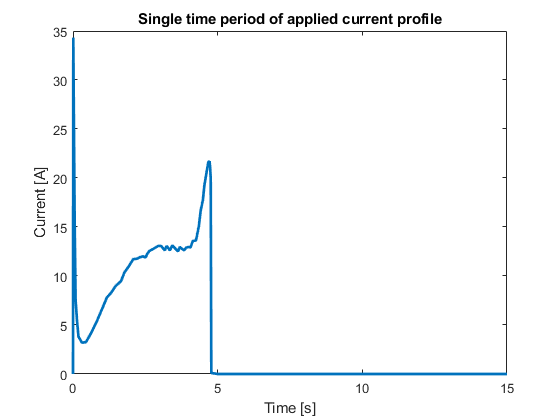

current_profile = readtable("data/electric_current.xlsx");

plot(current_profile.t(1:54), current_profile.current(1:54), 'linewidth', 2);
title('Single time period of applied current profile')
xlabel('Time [s]')
ylabel('Current [A]')

Now we will connect the cells in series (5s1p circuit) and apply current profile to the newly created circuit.

circuit = ["cell_core_1", "cell_core2_1", "cell_core_3", "cell_core_4", ...
    "cell_core_5"];

model.createElectricCircuit('ele_circ', circuit, '5s1p');
model.setCurrentProfile('ele_circ', current_profile);

Next step will be applying initial and boundary conditions.

We will start by choosing ambient air temperature of 25 deg C and set it as a initial temperature of all components.

T_air = 25;
model.setIC(".*", 'T', T_air);

Then we will choose casing outside walls and apply cooling by natural convection.

casing_middle_wall_ids = [1, 2, 4, 6, 7, 8, 10, 14, 17, 20, 21, 23, 27, ...
    28, 30, 32, 35, 37, 42, 46, 47, 51, 52, 53, 60, 61, 62, 63, 65, 67, ...
    68, 71, 74, 75, 77, 84, 87];
casing_side_wall_ids = [2, 9, 12, 17];
casing_top_wall_ids = [1, 6, 16, 17, 19, 28, 37];

model.addBC("casing_middle_1_1", casing_middle_wall_ids, 'type', 'Robin', ...
    'alpha', 5, 'T_inf', T_air);

Adding new Boundary condition to component casing_middle_1_1.


model.addBC(["casing_side_1", "casing_side_2"] , casing_side_wall_ids, ...
    'type', 'Robin', 'alpha', 5, 'T_inf', T_air);

Adding new Boundary condition to component casing_side_1.
Adding new Boundary condition to component casing_side_2.


model.addBC("casing_top_1_1", casing_top_wall_ids, 'type', 'Robin', ...
    'alpha', 5, 'T_inf', T_air);

Adding new Boundary condition to component casing_top_1_1.


To account for heat generation due to losses in components such as connectors, transistors etc. we will ready the .xlsx file with the heat source profile and apply it to the chosen components.

loses = readtable('data/loses.xlsx');

model.addST(["connector1_1", "connector1_2", "connector1_3", "connector1_4"], ...
    'Q', [loses.time loses.c1]);

Adding Source Term of component connector1_1.
Adding Source Term of component connector1_2.
Adding Source Term of component connector1_3.
Adding Source Term of component connector1_4.


model.addST(["connector2_1", "connector2_2"], 'Q', [loses.time loses.c2]);

Adding Source Term of component connector2_1.
Adding Source Term of component connector2_2.


model.addST("bus_bar1_1_1", 'Q', [loses.time loses.bb1]);

Adding Source Term of component bus_bar1_1_1.


model.addST("bus_bar2_1_1", 'Q', [loses.time loses.bb2]);

Adding Source Term of component bus_bar2_1_1.


model.addST(["transistor_1", "transistor_2", "transistor_3"], ...
    'Q', [loses.time loses.t]);

Adding Source Term of component transistor_1.
Adding Source Term of component transistor_2.
Adding Source Term of component transistor_3.


As a last step we will change initial cells charging state to 80%.

for i = 1:numel(model.electro_bodies)
    model.electro_bodies(i).SOC0 = 0.8;
end

## Simulation run

Now it is time to prepare our model for simulation. Q-Bat is based on the Reduced Order Modeling approach and requires an additional step of model assemblation and reduction but allows to perform simulation substantially faster. If you have access to MATLAB's parallel toolbox you can uncomment the first line of code and additionally increase simulation by allowing parallel computing.

% model.flag_is_parallel = true;
tic;
model_struct = model.prepare();

Elapsed linear fem grid assemblation time: 0.43132s.
Elapsed linear fem grid assemblation time: 0.09307s.
Elapsed linear fem grid assemblation time: 3.4304s.
Elapsed linear fem grid assemblation time: 0.11275s.
Elapsed linear fem grid assemblation time: 0.37292s.
Elapsed linear fem grid assemblation time: 0.10311s.
Elapsed linear fem grid assemblation time: 0.012034s.
Elapsed linear fem grid assemblation time: 0.072017s.
Assembling electro grid 1/2
Elapsed electro grid assemblation time: 0.017026s.
Assembling electro grid 2/2
Elapsed electro grid assemblation time: 0.010914s.
Assembling fem body: casing_side_1, number: 1/28
Elapsed body assemblation time: 0.0019601s.
Assembling fem body: casing_side_2, number: 2/28
Elapsed body assemblation time: 0.0016992s.
Assembling fem body: casing_top_1_1, number: 3/28
Elapsed body assemblation time: 0.0036375s.
Assembling fem body: casing_middle_1_1, number: 4/28
Elapsed body assemblation time: 0.10799s.
Assembling fem body: bus_bar1_1_1, number:

model_prepare_time = toc;
fprintf("Model preparation took %4.1f seconds.", model_prepare_time)

Model preparation took 449.3 seconds.

You can save already prepared model to re-use it later with different current profile, ambient temperature etc.

%save('model_struct.mat','model_struct');
%model.saveModel('model_preped.mat');

Finally, we can run our model. We will simulate 360 s of battery pack operation with a time step of 1 s.

tic;
model.run(1, 360, 'maxSubIter', 20, 'electroSubsteps', 20, 'solver', 'Direct');

Time step: 1, real time: 1.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:41:04
Time step: 2, real time: 2.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:41:05
Time step: 3, real time: 3.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:41:05
Time step: 4, real time: 4.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:41:05
Time step: 5, real time: 5.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:41:06
Time step: 6, real time: 6.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:41:06
Time step: 7, real time: 7.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:41:06
Time step: 8, real time: 8.000, no. subiters: 2, maxTempeatureRes: 0.

model_run_time = toc;
fprintf("Simulation run took %4.1f seconds.", model_run_time)

Simulation run took 121.7 seconds.

We can track temperature change of components as a trend plots or 3D temperature fileds.

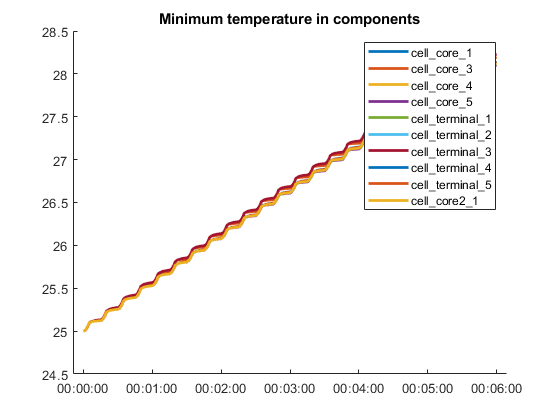

model.plotMinTempOverTime("cells_together")

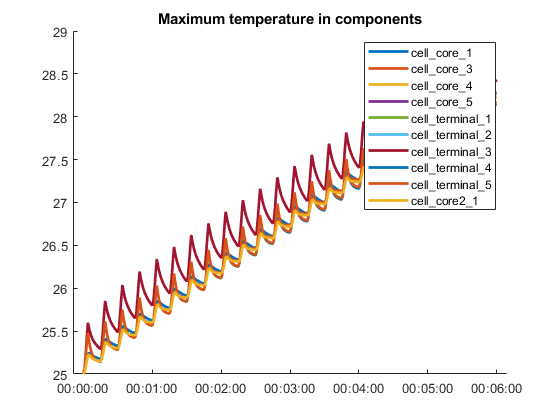

model.plotMaxTempOverTime("cells_together")

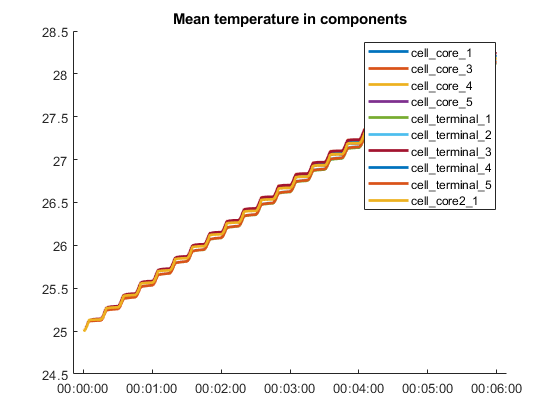

model.plotMeanTempOverTime("cells_together")

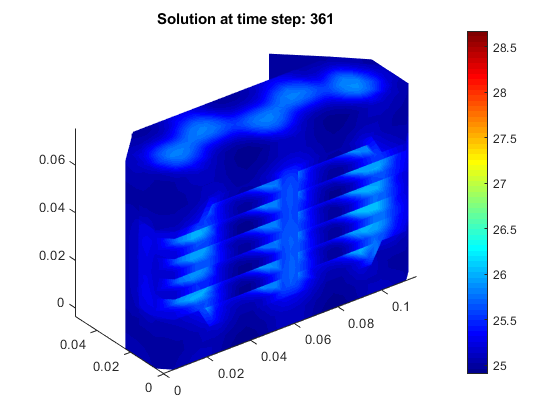

model.plotSolution()

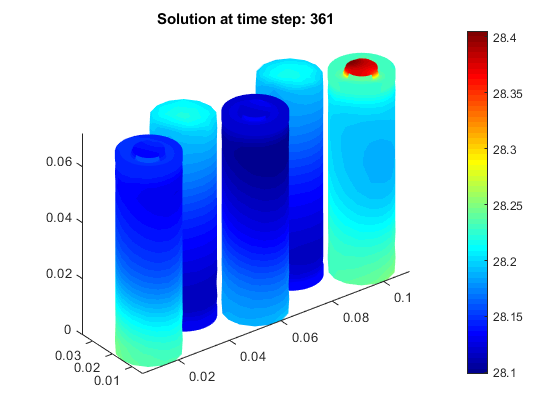

model.plotSolution(cells)

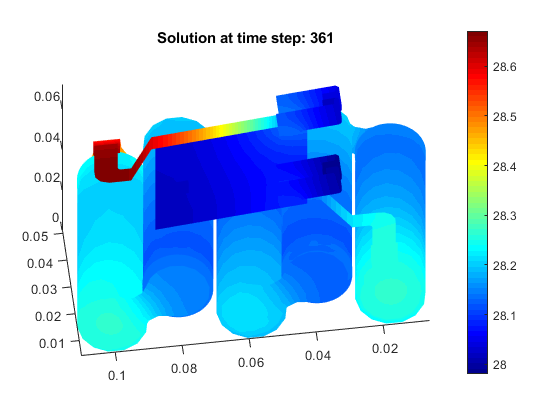

model.plotSolution([cells, misc_parts])

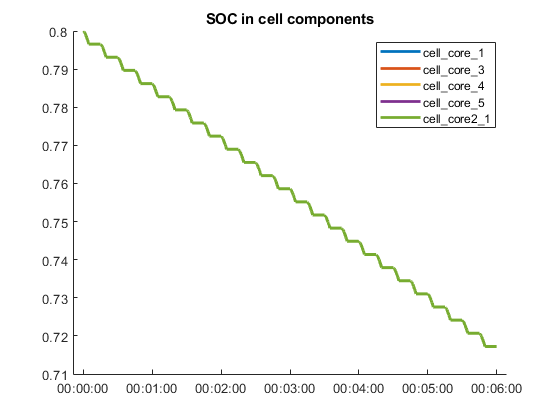

model.plotSOCOverTime()

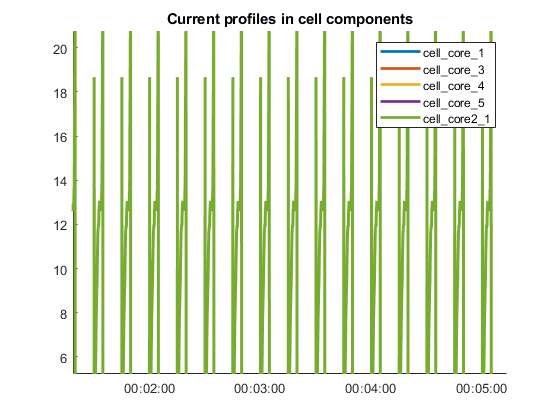

model.plotCurrentOverTime()

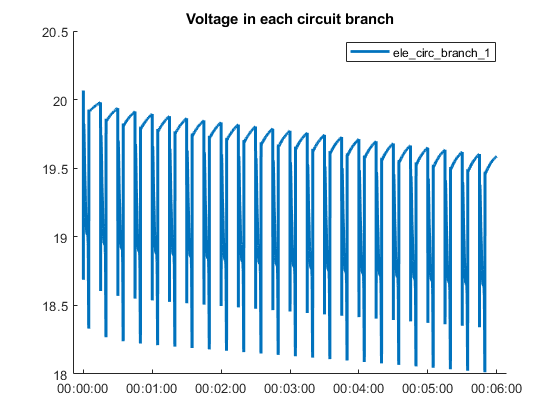

model.plotCircuitVoltage()

Full 3D temperature profile can be exported to CGNS file to be examined in other post-processing software such as Paraview.

% model.exportSolutionToCGNS(".*", 'power_tools.cgns', 181);

## Example 2 - Rapid charging

Now we will change the current profile to rapid charging for half an hour with a constant current of 40 A. Also, the initial state of cells will be changed to fully discharged.

model_struct.ele_circ_electro = [0 1800; -6 -6];

for i = 1:numel(model.electro_bodies)
    model.electro_bodies(i).SOC0 = 0;
end

Because we have already prepared the model and introduced only minor changes we can start the simulation almost immediately.

tic;
model.prepare();

This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
Assembling electro grid 1/2
Elapsed electro grid assemblation time: 0.017132s.
Assembling electro grid 2/2
Elapsed electro grid assemblation time: 0.015512s.
Assembling fem body: casing_side_1, number: 1/28
This body was already assembled, skipping.
Assembling fem body: casing_side_2, number: 2/28
This body was already assembled, skipping.
Assembling fem body: casing_top_1_1, number: 3/28
This body was already assembled, skipping.
Assembling fem body: casing_middle_1_1, number: 4/28
This body was already assembled, skipping.
Assembling fem body: bus_bar1_1_1, number: 5/28
This body was already assembled, skipping.
Assembling fem body: board_1_1, nu

model_prepare_time2 = toc;
fprintf("Model preparation took %4.1f seconds.", model_prepare_time2)

Model preparation took  5.3 seconds.

As you can see, model assemblation took only a fraction of the time needed to prepare the model for the first time.

This time we will simulate 1800 s of operation with 10 s time steps. Let's run the model.

tic;
model.run(10, 180, 'maxSubIter', 20, 'electroSubsteps', 20, 'solver', 'Direct', ...
    'signals_data', model_struct);

Time step: 1, real time: 10.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:44:13
Time step: 2, real time: 20.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:44:14
Time step: 3, real time: 30.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:44:14
Time step: 4, real time: 40.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:44:14
Time step: 5, real time: 50.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:44:15
Time step: 6, real time: 60.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:44:15
Time step: 7, real time: 70.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:44:15
Time step: 8, real time: 80.000, no. subiters: 2, maxTempeatur

model_run_time2 = toc;
fprintf("Simulation run took %4.1f seconds.", model_run_time2)

Simulation run took 60.9 seconds.

It took just a couple of seconds to check another current profile and obtain a complete set of results.

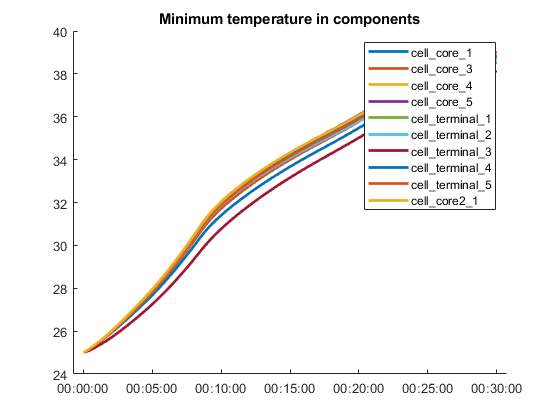

model.plotMinTempOverTime("cells_together")

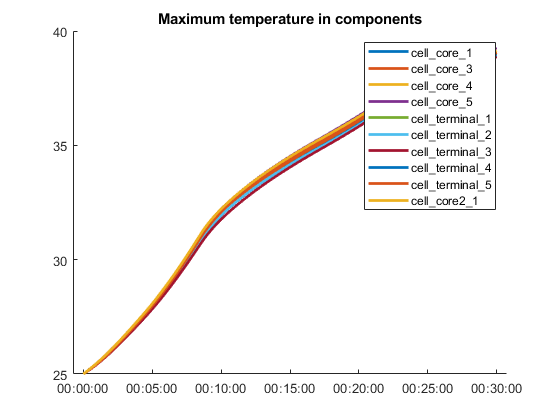

model.plotMaxTempOverTime("cells_together")

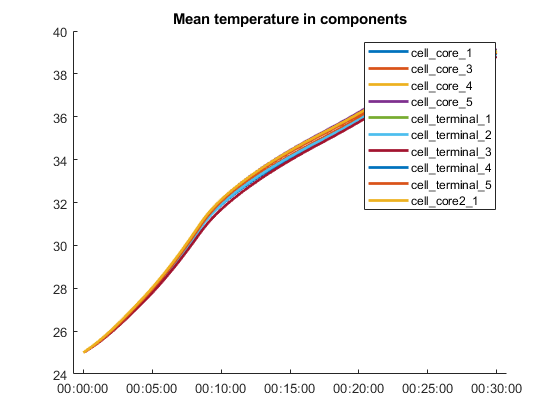

model.plotMeanTempOverTime("cells_together")

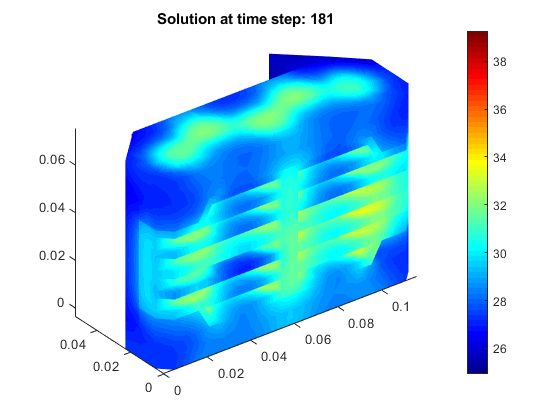

model.plotSolution()

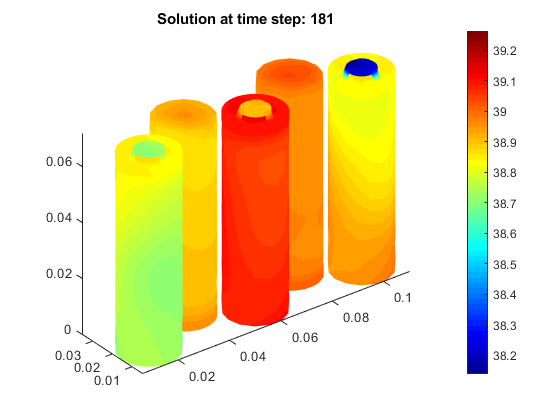

model.plotSolution(cells)

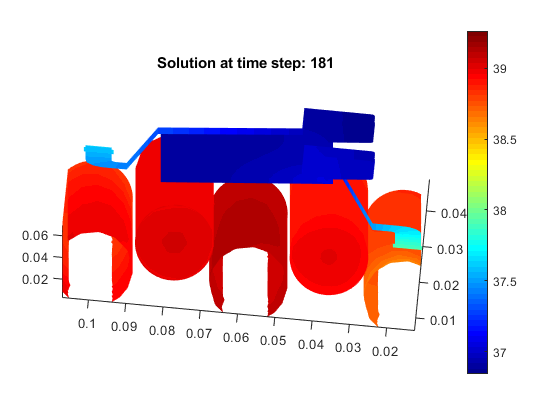

model.plotSolution([cells, misc_parts])

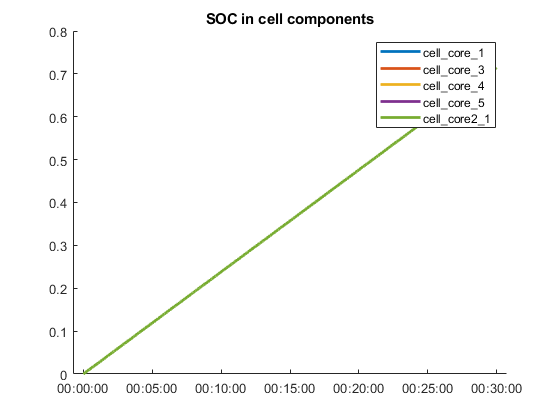

model.plotSOCOverTime()

## Example 3 - Thermal propagation

Now we will simulate thermal propagation. We will increase the resistance of a single cell to imitate its malfunction and see how the temperature increases.

model.electro_grids(2).R1_charge(:,3) = table(model.electro_grids(2).R1_charge{:,3} * 2);

We need to prepare our model again however, it will be much faster as most of it is the same as before.

tic;
model.prepare();

This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
This grid was already assembled, skipping.
Assembling electro grid 1/2
Elapsed electro grid assemblation time: 0.018736s.
Assembling electro grid 2/2
Elapsed electro grid assemblation time: 0.0085644s.
Assembling fem body: casing_side_1, number: 1/28
This body was already assembled, skipping.
Assembling fem body: casing_side_2, number: 2/28
This body was already assembled, skipping.
Assembling fem body: casing_top_1_1, number: 3/28
This body was already assembled, skipping.
Assembling fem body: casing_middle_1_1, number: 4/28
This body was already assembled, skipping.
Assembling fem body: bus_bar1_1_1, number: 5/28
This body was already assembled, skipping.
Assembling fem body: board_1_1, n

model_prepare_time3 = toc;
fprintf("Model preparation took %4.1f seconds.", model_prepare_time3)

Model preparation took  5.4 seconds.

Let's run the model again and see how did it change.

tic;
model.run(10, 180, 'maxSubIter', 20, 'electroSubsteps', 20, 'solver', 'Direct', ...
    'signals_data', model_struct);

Time step: 1, real time: 10.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:47:14
Time step: 2, real time: 20.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:47:15
Time step: 3, real time: 30.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:47:15
Time step: 4, real time: 40.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:47:15
Time step: 5, real time: 50.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:47:16
Time step: 6, real time: 60.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:47:16
Time step: 7, real time: 70.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 01-Feb-2022 09:47:16
Time step: 8, real time: 80.000, no. subiters: 2, maxTempeatur

model_run_time3 = toc;
fprintf("Simulation run took %4.1f seconds.", model_run_time3)

Simulation run took 61.0 seconds.

As you can see, one cell is significantly hotter than the rest, which results in heat propagating to the neighbouring cells.

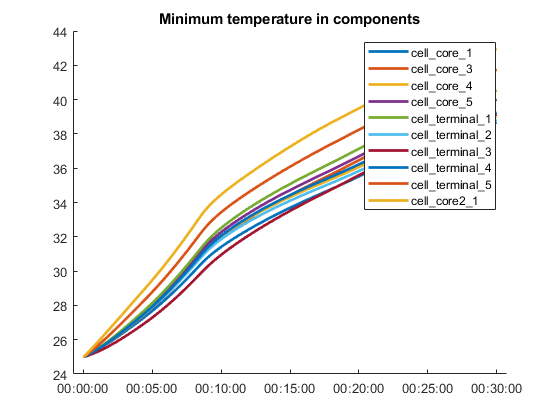

model.plotMinTempOverTime("cells_together")

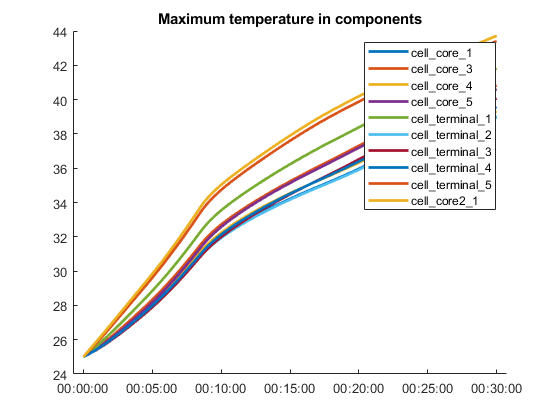

model.plotMaxTempOverTime("cells_together")

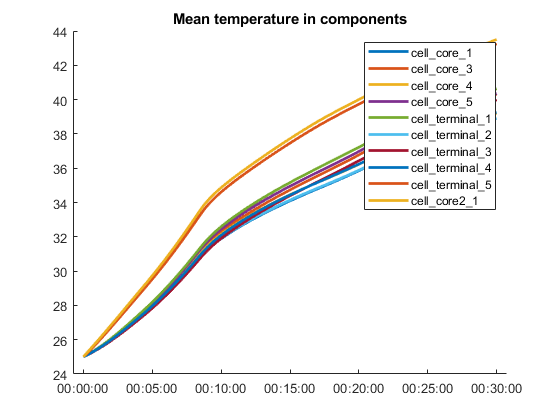

model.plotMeanTempOverTime("cells_together")

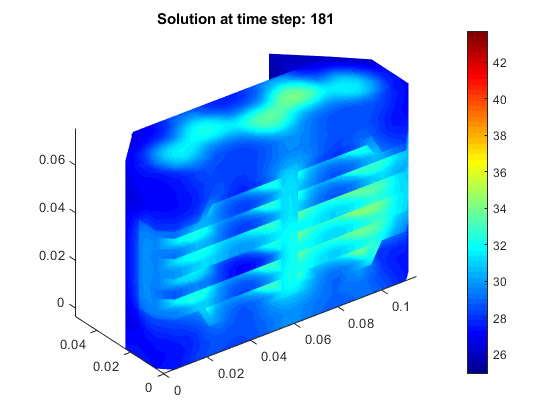

model.plotSolution()

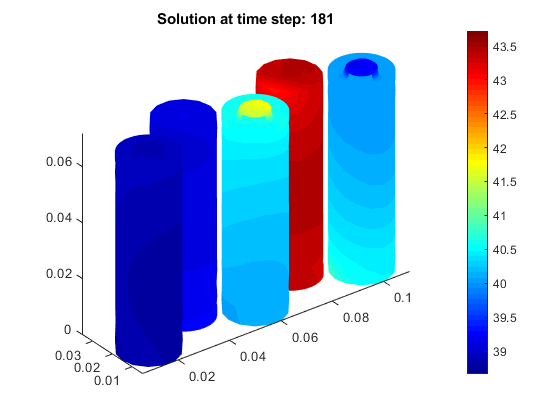

model.plotSolution(cells)

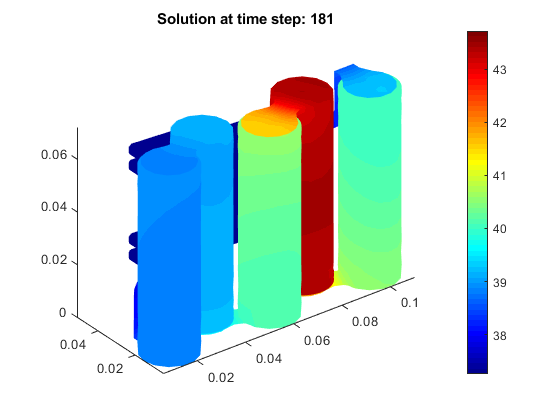

model.plotSolution([cells, misc_parts])